imnum = 50

% ok lets gooooooooooooo!!!!!
% testim = imread("CV_zebracrossing_images/pic1.jpg");
% imshow(testim)

Imfolder = 'CV_zebracrossing_images';
if ~isfolder(Imfolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', Imfolder);
  uiwait(warndlg(errorMessage));
  return;  
end

% Get a list of all image files in the folder
imageFiles = dir(fullfile(Imfolder, '*.jpg')); 

imnum = numel(imageFiles)
stockImages = cell(1, imnum);
images = cell(1, imnum);
imheight = zeros(1, imnum);
imcropped = cell(1, imnum);
imgray = cell(1,imnum);
k_threshold = zeros(1, imnum);
binim = cell(1,imnum);
medgray = zeros(1,imnum);
gaussianFilter = fspecial('gaussian', [5 5], 2);
imfiltered = cell(1,imnum);
edgedetected1 = cell(1,imnum);
edgedetected2 = cell(1,imnum);
edgedetected = cell(1,imnum);

for idx = 1:3
    filename = fullfile(Imfolder, imageFiles(idx).name);
    stockImages{idx} = imread(filename);
    %resize all images to one size for optimal cropping
    images{idx}=imresize(stockImages{idx},[300,600]);
    imcropped{idx} = imcrop(images{idx}, [0.5 133 600 167]);
    
    %my new code:
    %create a grayscale image 
    imgray{idx} = im2gray(imcropped{idx});
    medgray(idx) = mean(imfiltered{idx}(:));

    %defining threshold & apllying it to images
    k_threshold(idx) =  medgray(idx) * 1.7;
    if k_threshold < 50
        k_threshold = 100;
    end
    imfiltered{idx} = imfilter(imgray{idx}, gaussianFilter, 'conv', 'replicate');
    binim{idx} = imfiltered{idx} > k_threshold(idx);
    %displaying it

    
    %im_h = histogram(grayImage(grayImage>0));
    
    %edgedetected1{idx} = edge(imfiltered{idx}, 'canny', 0.3);
    edgedetected{idx} = edge(imfiltered{idx}, 'canny');
    %edgedetected{idx} = edgedetected2{idx} - edgedetected1{idx};
    
    figure(2);
    subplot(2, 2, idx);
    imshow(edgedetected{idx});
end


for i = 1:imnum 
   
end

% for i = 1:imnum
%     imshow(imcropped{i});
% end

code snipped for threshold adjustment on only one pic

%create a grayscale image 
grayImage = rgb2gray(images{47});

%get the histogram and display both
figure(1);
subplot(1, 2, 1);
im_h = histogram(grayImage(grayImage>0));
hold on
%calculate and display average
durchschnitt = mean(grayImage(:))

durchschnitt = 39.6799

xline(durchschnitt, 'Color', 'r', 'LineWidth', 2);


% Display the gray scale image.
subplot(1, 2, 2);
imshow(grayImage, []);

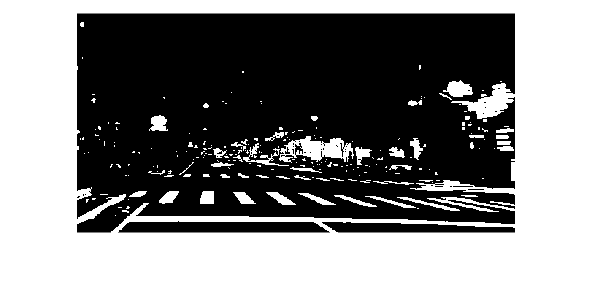



kThreshold = durchschnitt*1.7;
zebraCrossing = grayImage > kThreshold;

figure(2);
subplot(1, 1, 1);
imshow(zebraCrossing);